# Graficos 2D

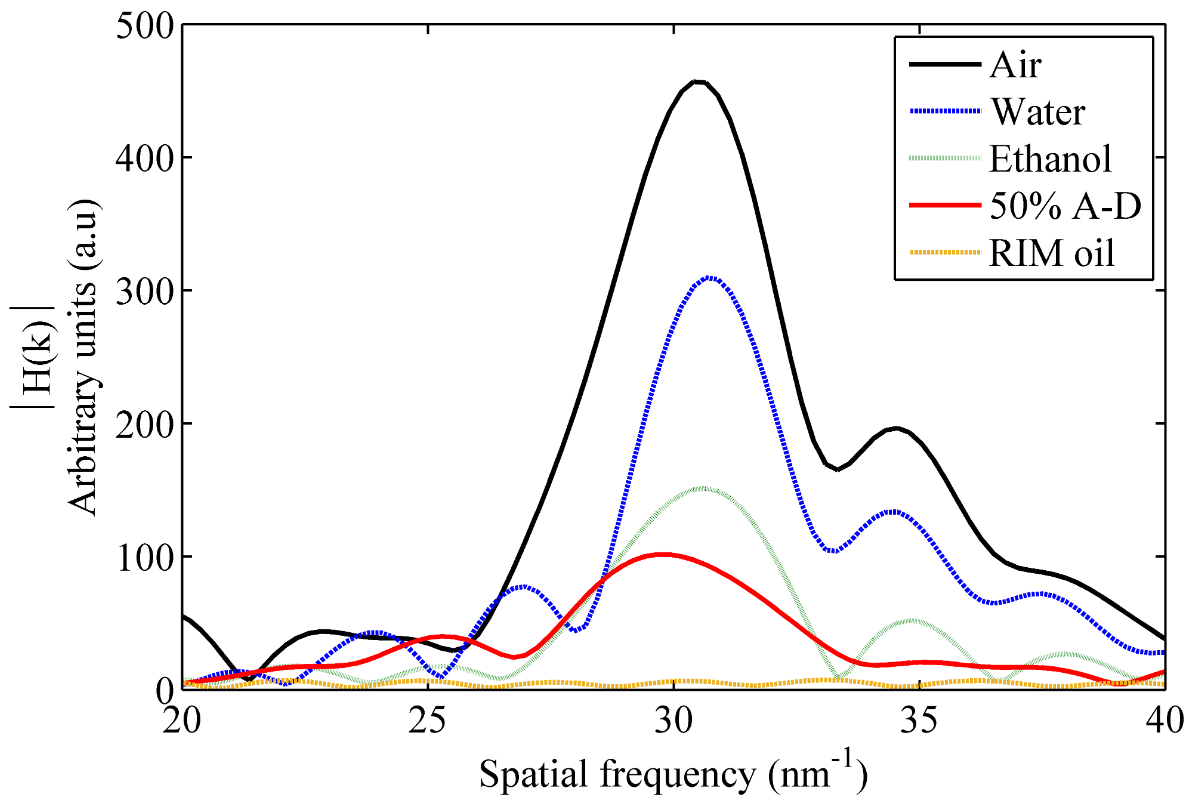

## Introducción

La representación de datos es una de las funciones básicas de cualquier software matemático. La visualización de los datos de forma gráfica nos permite obtener gran cantidad de información de forma rápida e intuitiva.

    MATLAB dispone de múltiples funciones que permiten la representación y el análisis de datos, la visualización y procesado de imágenes o incluso la creación de videos y animaciones. A continuación veremos las funciones más importantes de las que dispone MATLAB para la representación de datos en dos dimensiones.

    En MATLAB existen dos formas de crear gráficos: 

-     Mediante comandos, bien en la ventana de comandos o en un *script*.

-     Mediante la interfaz gráfica, utilizando las funciones que aparecen en la pestaña PLOTS. 

    Ambas son equivalentes. Sin embargo, los comandos son casi imprescindibles cuando se trabaja con funciones o scripts o cuando el número de gráficas a representar es elevado.

## Las figuras

MATLAB se basa en un lenguaje de programación orientado a objetos. Todo en MATLAB es un objeto, desde los elementos de la interfaz gráfica hasta las variables. Algunos objetos tienen representación gráfica, es decir, que los podemos ver en la interfaz, y otros no. Los objetos tienen propiedades y métodos (funciones) que nos permiten desde crear nuevos objetos hasta acceder a sus propiedades y modificarlas.

    La siguiente imagen muestra un ejemplo de figura de MATLAB. Las figuras son ventanas independientes que pueden contener uno o más ejes (axes), leyendas y otro tipo de objetos. Cada uno de estos objetos tienen propiedades que se pueden modificar para controlar su aspecto. 

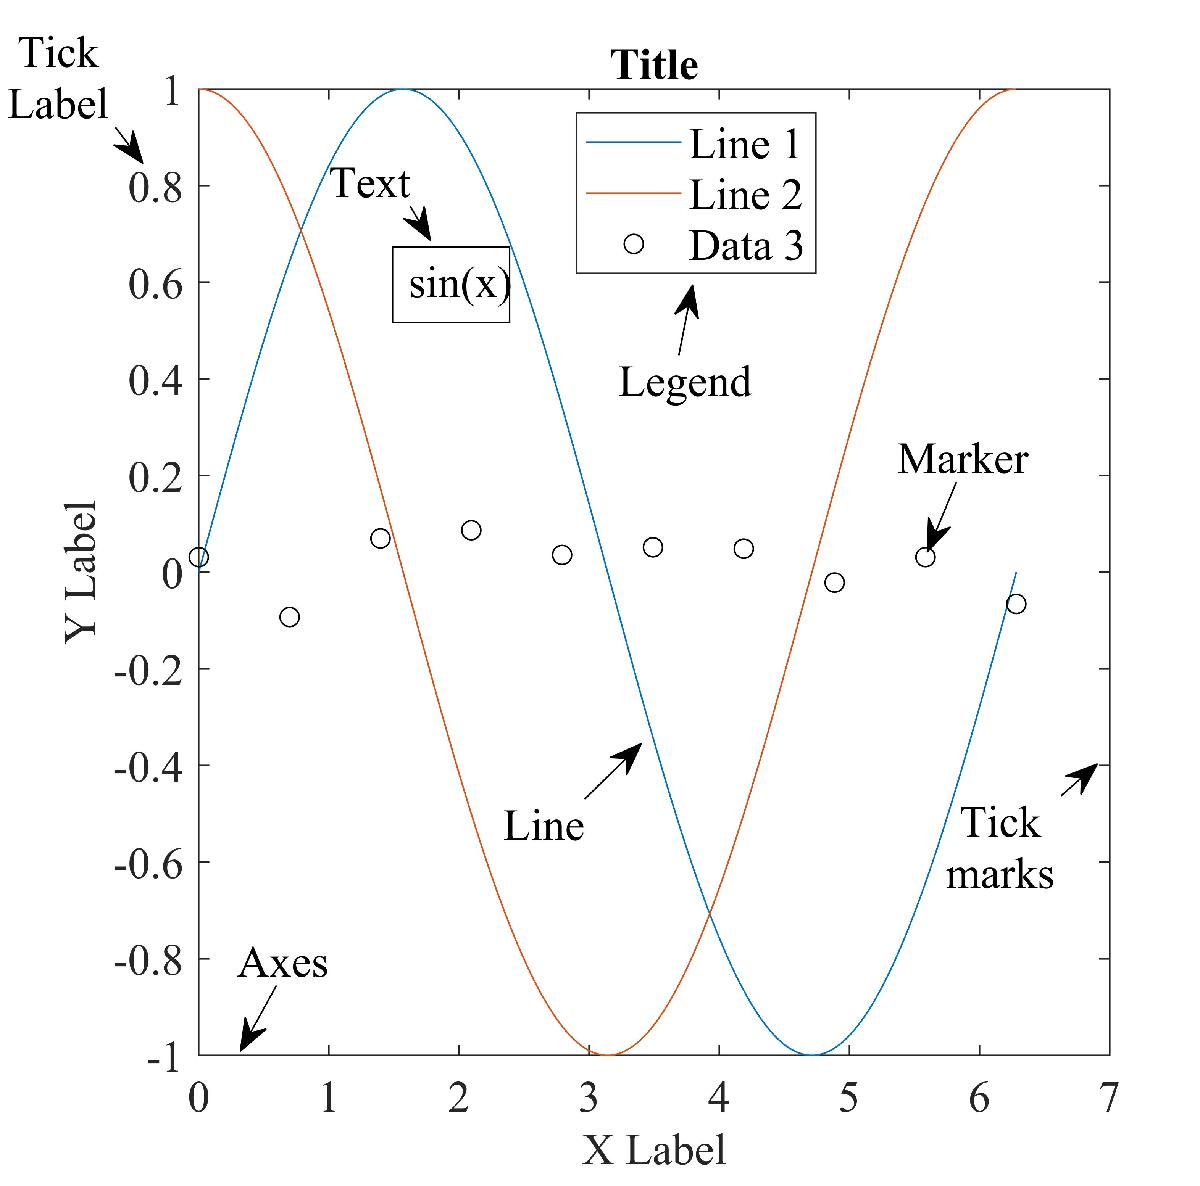

    Los objetos de una figura siguen una jerarquía padre/hijo. 

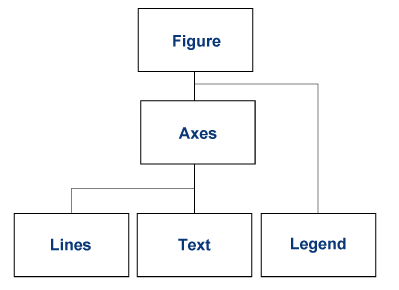

## Funciones

### figure

La función *figure, *utilizada en la ventana de comandos, crea una nueva figura. Esta figura puede múltiples objetos. Puede obtener más información acerca de la funcionalidad de esta función en la ayuda de MATLAB. La función figure no funciona del mismo modo en el live script ya que las figuras se crean en la salida del live script en lugar de una ventana diferente.

help figure

figure - Create figure window

    This MATLAB function creates a new figure window using default property values.

    figure
    figure(Name,Value)
    f = figure(___)
    figure(f)
    figure(n)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/axes.html">axes</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/cla.html">cla</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/clf.html">clf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/gca.html">gca</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/gcf.html">gcf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/shg.html">shg</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/matlab.ui.figure-properties.html">Figure Properties</a>

    Documentation for figure



    Pruebe a escribir *figure,* en la ventana de comandos. Las figuras, como cualquier otro objeto, tienen atributos (o propiedades). En la ventana de la figura vaya a *View *y luego a *Property Inspector* para ver las propiedades que controlan el aspecto y funcionalidad de la figura*. *Más adelante utilizaremos el* Property Inspector* para ver y modificar otros objetos.

    Las figuras pueden cerrarse desde la ventana de comando o un *script* mediante la función *close*, indicando el número de figura o bien mediante la palabra *all* si queremos cerrar todas las figuras.

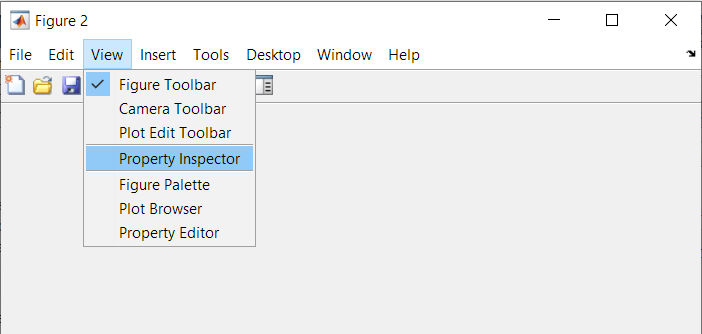

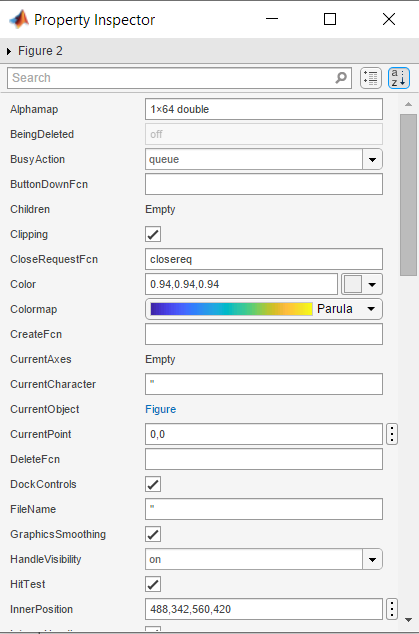

### plot

La función *plot* permite crear una curva en un espacio bidimensional. 

    Esta función también crea, si es necesario, una nueva figura y los ejes de nuestro gráfico. Es conveniente utilizar la función *figure *antes de plot si se quieren mantener las figuras anteriores.

help plot         % Ayuda de la función 

plot - 2-D line plot

    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    plot(X,Y)
    plot(X,Y,LineSpec)
    plot(X1,Y1,...,Xn,Yn)
    plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
    plot(Y)
    plot(Y,LineSpec)
    plot(___,Name,Value)
    plot(ax,___)
    h = plot(___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/gca.html">gca</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/hold.html">hold</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/legend.html">legend</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/loglog.html">loglog</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/plot3.html">plot3</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/title.html">title</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/xlabel.html">xlabel</a>, <a href="https://www.ma

    Esta función por lo general tiene dos parámetros de entrada, *X* e *Y, *que normalmente son vectores o matrices. Los valores de X e Y forman pares $\left(X_i ,Y_i \right)$ que representan las coordenadas de los puntos que forman parte de la gráfica. 

    Si quisieramos únicamente representar un punto situado en la coordenada (3,1) escribiríamos una instrucción como la siguiente:

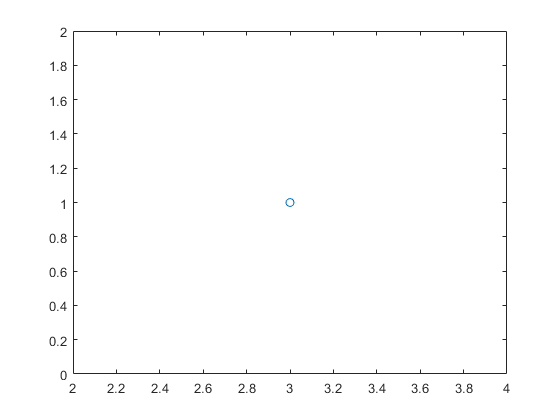

figure
plot(3,1,'o')

    Para mejorar la visualización utilizamos el argumento 'o', que le indica a la función plot que debe utilizar círculos en lugar de puntos. Puede encontrar más opciones de visualización en la ayuda del comando plot.

    Evidentemente la representación de un único punto no nos aporta información de utilidad pero nos sirve para comprender el funcionamiento básico de la función plot.

    Para representar más puntos creamos más pares en los vectores X e Y. Note que la longitud de ambos vectores es la misma.

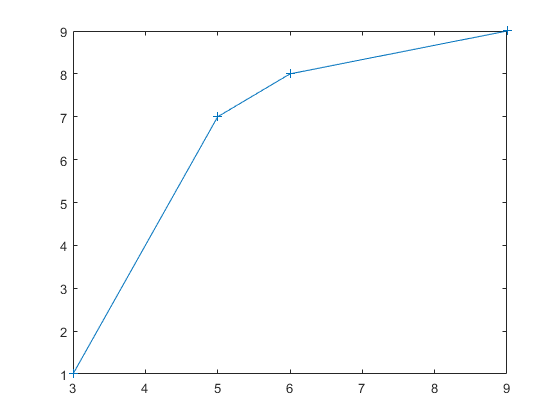

figure
plot([3,5,6,9],[1,7,8,9],'-+')

    En un caso más general, para representar la función$y=f\left(x\right)$, siendo x la variable independiente seguiríamos los siguientes pasos:

- Creamos el vector con los valores de la variable independiente

- Evaluamos la función en cada uno de los valores de la variable independiente

- Utilizamos la función plot para representar la función. 

    Veamos un ejemplo de estos pasos para representar la función $y=x^2$ en el intervalo [-100, 100].

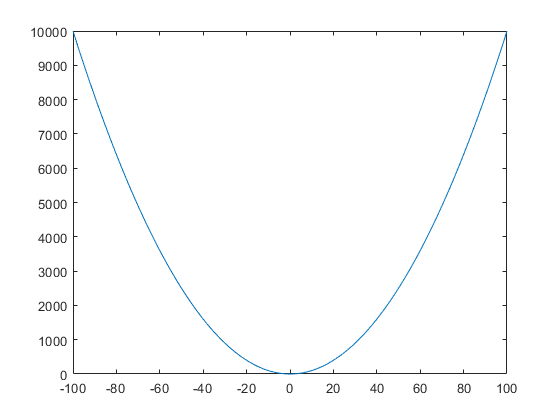

figure
x=linspace(-100,100,1001);        % Creamos la variable independiente
y=x.^2;                           % Evaluamos la función
plot(x,y)                         % Representamos la función

    La función plot permite representar más de una función al mismo tiempo siguiendo la siguiente estructura $\textrm{plot}\left(\textrm{x1},\textrm{y1},\textrm{x2},\textrm{y2},\ldotp \ldotp \ldotp \right)$

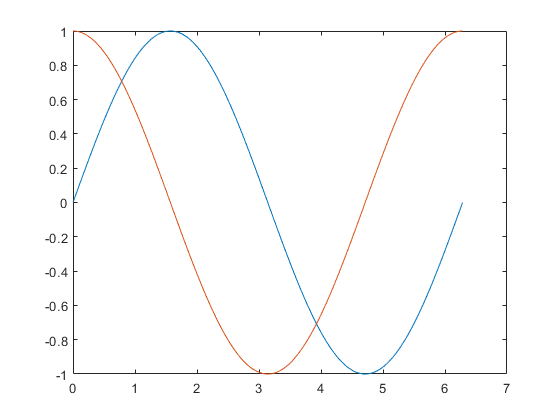

figure
x2=linspace(0,2*pi,1000);        % Utilizaremos la misma variable independiente
y1=sin(x2);
y2=cos(x2);
plot(x2,y1,x2,y2)

Alternativamente se puede utilizar el comando *hold*.

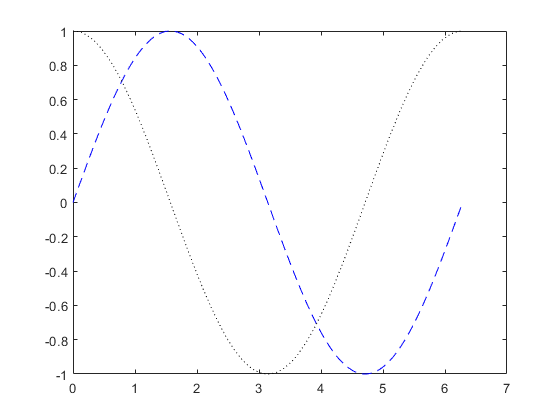

figure
plot(x2,y1,'b--')              
hold on                         % Activamos el comando hold
plot(x2,y2,'k:')
hold off                        % Desactivamos el comando hold  

#### Ejercicio 1

Represente la función $y=\frac{\sin \left(x\right)}{x}$ en el intervalo [-20, 20] con 1001 puntos.

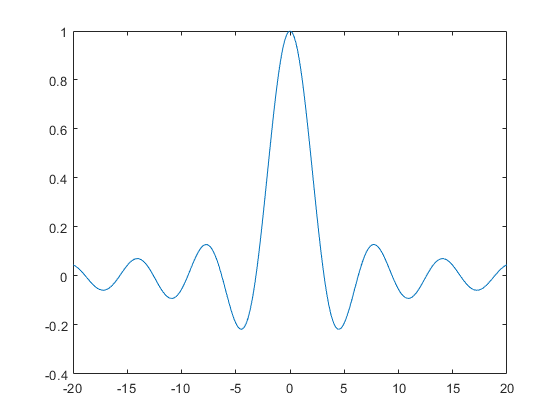

x = linspace(-20,20,1001);
y = sin(x)./x; %Es una función sinc.
plot(x,y)

    En el comando plot los argumentos X e Y pueden ser matrices. Veamos un ejemplo representando la función $y=x^{\alpha }$ para distintos valores de $\alpha$.

    En primer lugar definimos nuestra variable independiente en el intervalo [0, 1]. A continuación definimos los valores de $\alpha$. Y evaluamos la función.

x3=0:0.01:1;
a=[0.1,0.25,1,2,10]';       % Debe ser un vector columna
y3=x3.^a;

    Observa que la variable y3 es una matriz con un número de filas igual al número de valores de $\alpha$ y un número de columnas coincidente con la longitud de la variable independiente, x3. 

        En el caso de matrices, MATLAB interpreta la forma de representar los datos. En este caso como la longitud de x3 es igual al número de columnas de y3 MATLAB representa cada fila como una función independiente. El comando *legend* crea una leyenda y especifica el nombre mostrado para cada una de las funciones. La función *grid* muestra una cuadrícula en el gráfico.

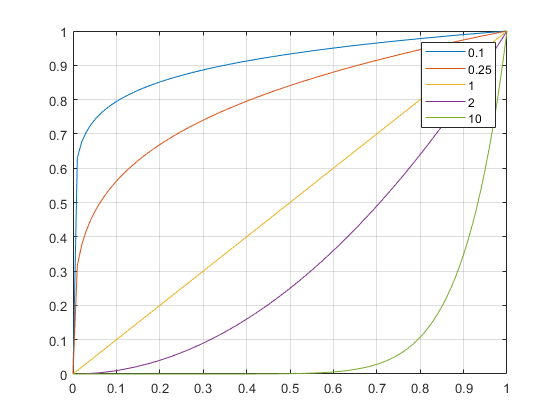

figure 
plot(x3,y3), legend('0.1','0.25','1','2','10'), grid

    Seleccione la figura recién creada. Al seleccionarla, en la parte superior derecha del gráfico aparecerá una flecha permite abrir el gráfico en una nueva ventana.  Utilizando la flecha de la barra de herramientas, seleccione alternativamente las líneas, la leyenda y los ejes, y utilizando el *Property Inspector* observe algunas de las propiedades de los objetos que componen la figura.  

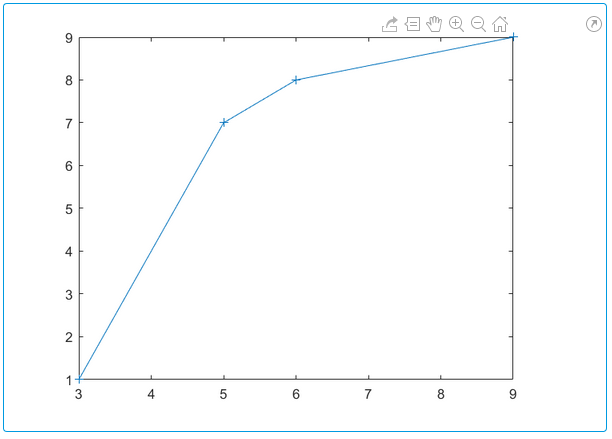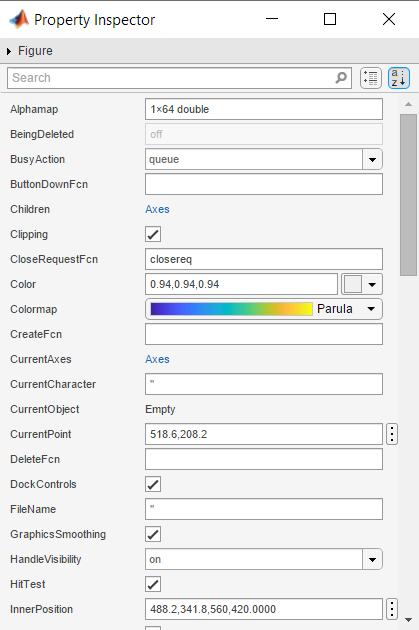

### xlabel, ylabel, title

Las funciones xlabel e ylabel nos permiten poner etiquetas a los ejes X e Y de un gráfico. La función title nos permite poner un título a nuestra gráfica. Observe la ayuda de estas funciones.

help xlabel

xlabel - Label x-axis

    This MATLAB function labels the x-axis of the current axes or standalone
    visualization.

    xlabel(txt)
    xlabel(target,txt)
    xlabel(___,Name,Value)
    t = xlabel(___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/num2str.html">num2str</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/text.html">text</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/title.html">title</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/ylabel.html">ylabel</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/zlabel.html">zlabel</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/matlab.graphics.primitive.text-properties.html">Text Properties</a>

    Documentation for xlabel



help title

title - Add title

    This MATLAB function adds the specified title to the current axes or standalone
    visualization.

    title(titletext)
    title(titletext,subtitletext)
    title(___,Name,Value)
    title(target,___)
    t = title(___)
    [t,s] = title(___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/subtitle.html">subtitle</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/xlabel.html">xlabel</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/ylabel.html">ylabel</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/zlabel.html">zlabel</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/matlab.graphics.primitive.text-properties.html">Text Properties</a>

    Documentation for title



#### Ejercicio 2

Represente la función $y\left(x\right)=\frac{1}{x}$, y ponga etiquetas a cada uno de los ejes y un título.

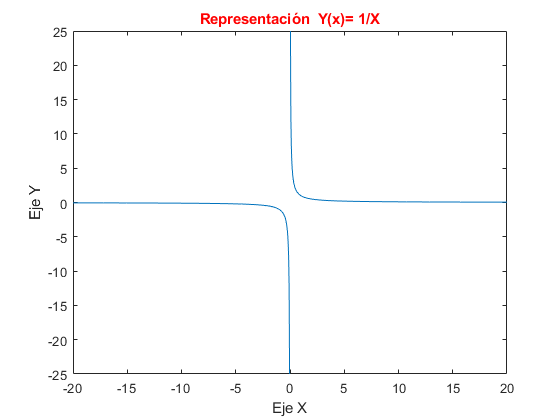

figure("Name","Ejercicio 2");
x = linspace(-20,20,1001);
y = 1./x;
plot(x,y);xlabel("Eje X");ylabel("Eje Y");title("Representación  Y(x)= 1/X",'Color','r')

### subplot

La función subplot nos permite crear más de un eje en una misma figura. Generalmente se utiliza con 3 argumentos. Los dos primeros argumentos indican el número de filas y columnas que dividen la figura. El tercer parámetro selecciona uno de los ejes. Esta función permite una notación rápida omitiendo las comas.

    Veamos un ejemplo. Vamos a dividir una figura para que contenga 2 ejes, uno situado a la derecha y otro a la izquierda. 

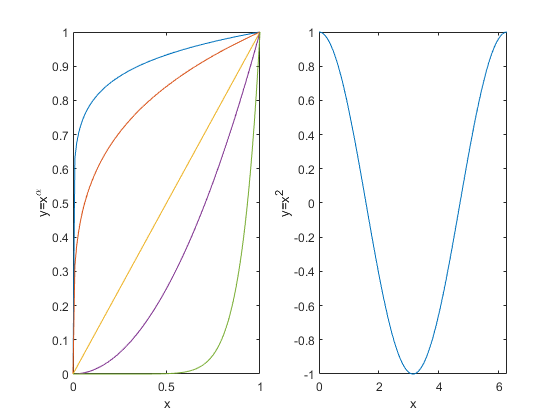

figure
subplot(1,2,1)
plot(x3,y3), xlabel('x'), ylabel('y=x^\alpha')
subplot(122)
plot(x2,y2), xlabel('x'), ylabel('y=x^2')

#### Ejercicio 3

Cree una figura con cuatro ejes. Dibuje una función distinta en cada uno de los ejes y escriba las leyendas de los ejes. Intente utilizar distintos colores para las líneas siguiendo la ayuda de la función plot.

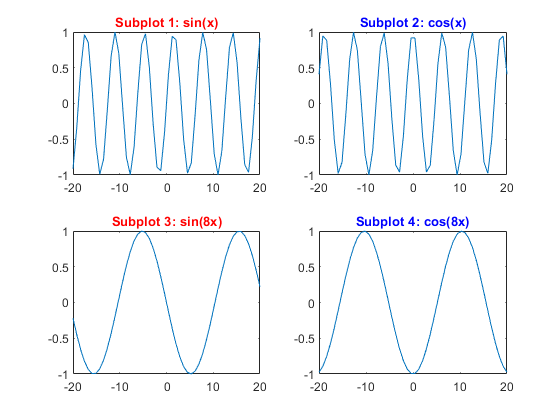

figure("Name","Ejercicio 3")
subplot(2,2,1)
x = linspace(-20,20,50);
funcion_1= sin(x);
plot(x,funcion_1);
title('Subplot 1: sin(x)','Color','r')

subplot(2,2,2)
funcion_2 = cos(x);
plot(x,funcion_2);
title('Subplot 2: cos(x)','Color','b');

subplot(2,2,3);
funcion_3 = sin(8*x);
plot(x,funcion_3);
title('Subplot 3: sin(8x)','Color','r');

subplot(2,2,4);
funcion_4 = cos(8*x);
plot(x,funcion_4);
title('Subplot 4: cos(8x)','Color','b');

### semilogx, semilogy, loglog

Estas tres funciones son similares a plot, pero permiten ponen uno o los dos ejes en escala logarítmica. Son de especial utilidad cuando se utilizan funciones logarítmicas y exponenciales. 

    Veamos un ejemplo donde se comparan las funciones plot y semilogy para representar exactamente la misma función.

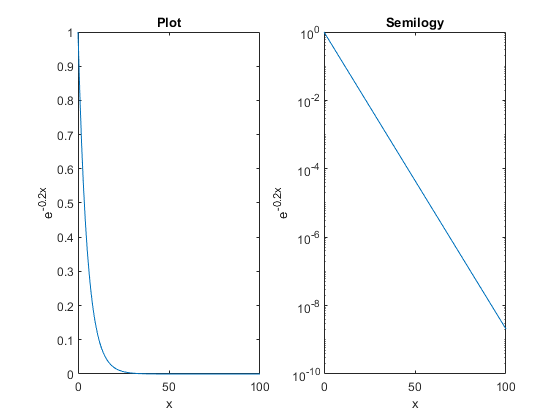

figure
subplot(121), plot(0:100,exp(-0.2*(0:100)))
xlabel('x'), ylabel('e^{-0.2x}'), title('Plot')
subplot(122), semilogy(0:100,exp(-0.2*(0:100)))
xlabel('x'), ylabel('e^{-0.2x}'), title('Semilogy')

### yyaxis

Cuando queremos representar en en mismo eje dos funciones que tienen la misma escala en el eje de abscisas (X) pero una escala diferente en el eje de ordenadas (Y) es conveniente utilizar la función yyaxis. Esta función permite crear un segundo eje de ordenadas o seleccionar cualquiera de los ejes si ambos ejes ya existieran. 

#### Ejercicio 4

Utilizando *yyaxis*, represente la función $v\left(t\right)=V\left(1-e^{-\frac{t}{\textrm{RC}}} \right)$ con $V=5$, $\textrm{RC}=0\ldotp 7$ en el eje de ordenadas izquierdo y la función $i\left(t\right)=I*\sin \left(\omega \cdot t\right)$ con $I=0\ldotp 1$ y $\omega =0\ldotp 5\cdot \pi$ en el eje de ordenadas derecho. En este caso la variable independiente es $t$, que representa el tiempo en segundos, $v\left(t\right)$ representa un voltaje medido en Voltios e $i\left(t\right)$ representa una corriente, medida en Amperios. Represente las funciones en el intervalo [0, 5] segundos con un mínimo de 50 puntos y etiquete los ejes correspondientes.

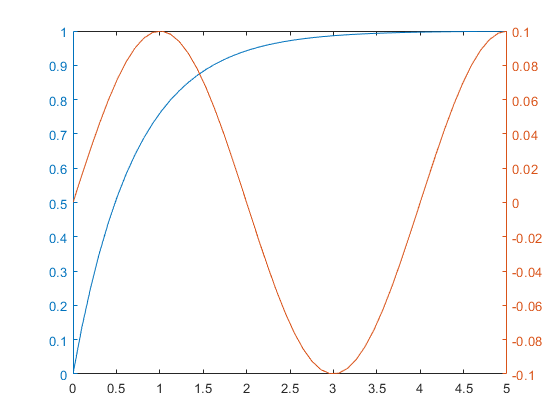

figure("Name","Ejercicio 4")
RC=0.7;V = 5; I = 0.1; W=0.5*pi;
t = linspace(0,5,50);
Funcion_V = 1 - exp((-t)/RC);
Funcion_I = I*sin(W*t);

yyaxis left;
plot(t,Funcion_V);ylabel("Tension")

yyaxis right;
plot(t,Funcion_I);

ylabel("Corriente");
xlabel("Tiempo")



### scatter

La función *scatter* crea un tipo de gráficos distinto a los anteriores que hemos visto. Este tipo de gráficos es idóneo cuando, en principio, los datos no tienen una relación entre ellos, es decir, son datos dispersos. Veamos un ejemplo sencillo.

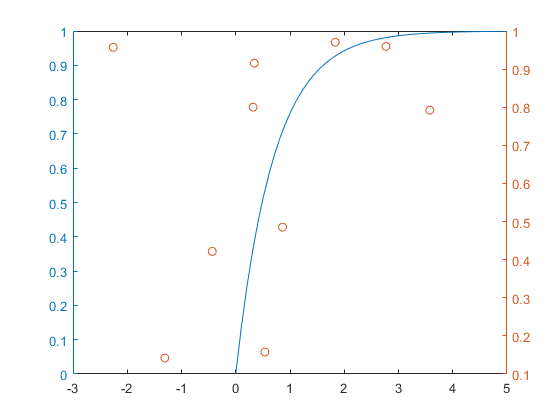

scatter(randn(1,10),rand(1,10))

La función *scatter* permite controlar el tamaño de los marcadores e incluso el color de los mismos.

    Imaginemos que queremos representar la temperatura en un determinado lugar a lo largo de un mes. Supondremos una temperatura media de 25ºC y una desviación estándar de 2ºC para generar los datos.

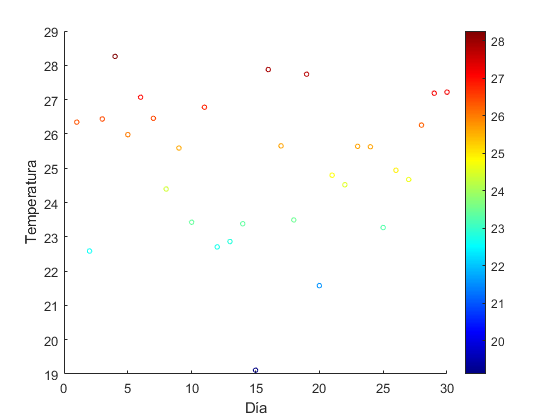

figure
T=25+2*randn(30,1);
scatter(1:30,T,12,T)
xlabel('Día'), ylabel('Temperatura')
colorbar
colormap jet

    Observe como varía el color de cada punto en función de la temperatura medida. Pruebe a cambiar el mapa de color abriendo el gráfico en una nueva ventana y con el botón derecho sobre el mapa de color de la figura.

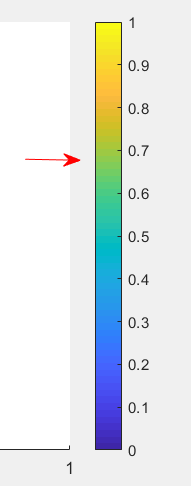

### stem

La función stem permite representar secuencias discretas. Esta función es muy utilizada en caso de discretización del tiempo.

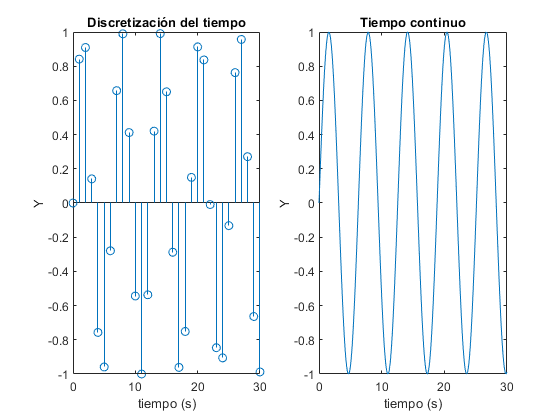

figure
subplot(121), stem(0:30,sin(0:30))
xlabel('tiempo (s)'), ylabel('Y'), title('Discretización del tiempo')
subplot(122), plot(0:0.1:30,sin(0:0.1:30))
xlabel('tiempo (s)'), ylabel('Y'), title('Tiempo continuo')

### stairs

La función stairs es utilizada para representar la discretización del eje de ordenadas.

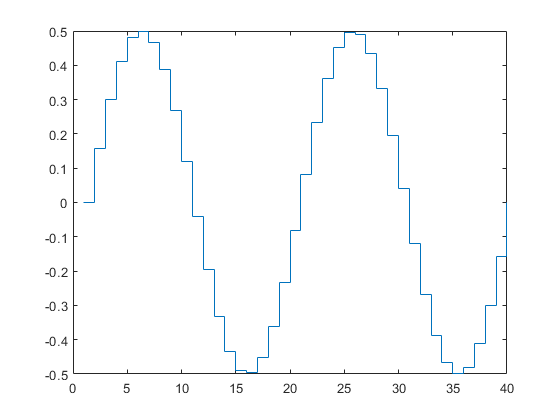

t = linspace(0,4*pi,40);
s = 0.5*sin(t);
figure
stairs(s)

### polarplot

La función *polarplot* representa un gráfico en coordenadas polares.

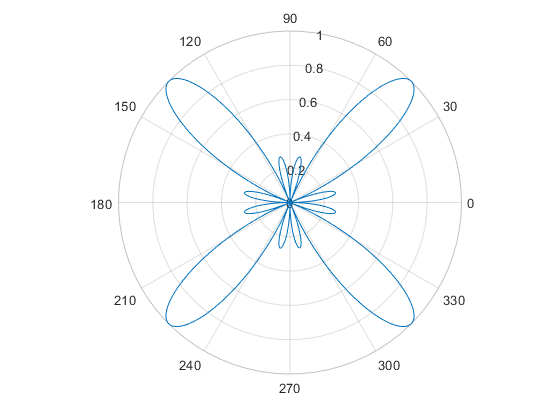

figure
theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(4*theta);
polarplot(theta,rho)

### bar

Esta función representa un gráfico de barras. Cada componente del vector indica la altura de las barras. La función *barh* es similar, con la diferencia en que las barras son horizontales.

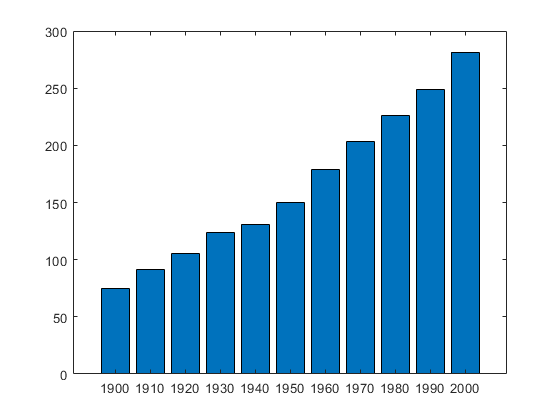

x = 1900:10:2000;
y = [75 91 105 123.5 131 150 179 203 226 249 281.5];
bar(x,y)

### pie

Representa un gráfico de sectores. Si la suma de los elementos es menor a 1, representará un gráfico de sectores no completo, si es mayor a 1 la función normaliza los valores para que su suma sea 1.

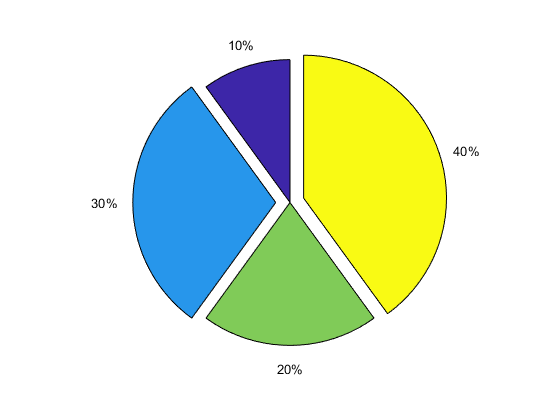

figure
pie([10,30,20, 40],[0 1 0 1])

### Contour

Esta función representa curvas de nivel. Se suele utilizar para representar funciones de dos variables independientes, $g=f\left(x,y\right)$. Veamos un ejemplo.

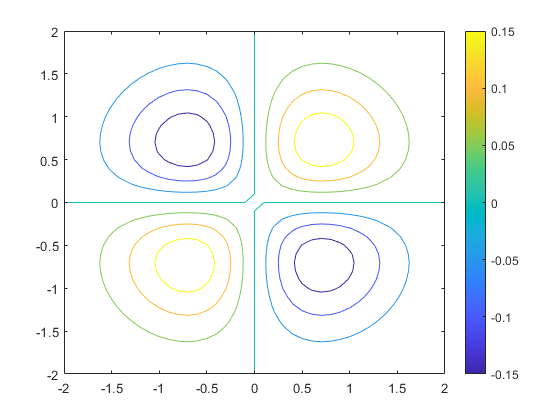

figure
x=-2:0.1:2;
y=-2:0.1:2;
[X,Y] = meshgrid(x,y);
g = X .* Y.* exp(-X.^2 - Y.^2);
contour(X,Y,g)
colorbar

La función *meshgrid* crea una malla con los puntos donde se evalúa la función bidimensional. Es común utilizarla juntamente con *contour* y otras funciones bidimensionales y en gráficos 3D.

Pruebe también a utilizar la función *contourf* en lugar de *contour*.

### pcolor

Esta función, al igual que la función anterior, representa funciones bidimiensionales. En lugar de curvas de nivel representa en falso color el valor de la función en cada uno de los puntos.

Utilizando el ejemplo anterior.

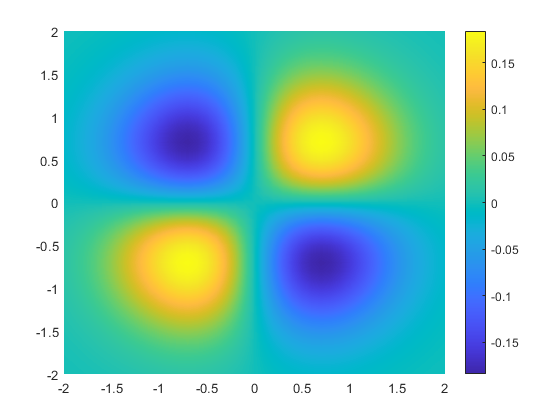

figure
x=-2:0.1:2;
y=-2:0.1:2;
[X,Y] = meshgrid(x,y);
g = X .* Y.* exp(-X.^2 - Y.^2);
pcolor(X,Y,g)
shading 'interp'
colorbar

### xlim, ylim

Al crear una gráfica, MATLAB por defecto ajusta los límites de los ejes automáticamente en función de los valores máximos y mínimos, pero en ocasiones nos interesa modificar estos límites para mejorar la visualización de los datos. En estos casos podemos utilizar las funciones *xlim* o *ylim* para modificar los límites de nuestra gráfica.

Vamos a mostrar un ejemplo. En este ejemplo vamos a representar un señal que cambia entre dos estados, de 0 a 1 de forma periódica. 

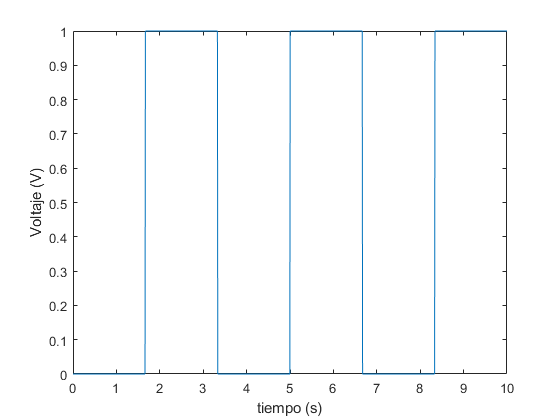

t=linspace(0,10,1200);      % tiempo
u=[zeros(1,200), ones(1,200), zeros(1,200), ones(1,200), zeros(1,200), ones(1,200)];
figure
lin=plot(t,u);
xlabel('tiempo (s)')
ylabel('Voltaje (V)')

Si se observa la figura recién creada, MATLAB ha utilizado el valor máximo de la señal para fijar el límite de la gráfica, limitando el eje de ordenadas a 1. 

#### Ejercicio 5

Modifique el ejemplo anterior para que la señal ahora alterne entre 0 y 1.15 usando la función *xlim*. Observe el resultado. ¿Qué ocurre con el límite de ordenadas?



t=linspace(0,10,1200);      % tiempo

         CallbackObject: [0×0 GraphicsPlaceholder]
               Children: [25×1 Figure]
          CurrentFigure: [1×1 Figure]
     FixedWidthFontName: 'Courier New'
       HandleVisibility: 'on'
       MonitorPositions: [1 1 1920 1080]
                 Parent: [0×0 GraphicsPlaceholder]
        PointerLocation: [1302 661]
            ScreenDepth: 32
    ScreenPixelsPerInch: 96
             ScreenSize: [1 1 1920 1080]
      ShowHiddenHandles: off
                    Tag: ''
                   Type: 'root'
                  Units: 'pixels'
               UserData: []



u=[zeros(1,200), ones(1,200), zeros(1,200), ones(1,200), zeros(1,200), ones(1,200)];
figure("Name","Ejercicio 5 a");
lin=plot(t,u);
xlim([0,1.5])
xlabel('tiempo (s)')
ylabel('Voltaje (V)')

                 Alphamap: [1×64 double]
             BeingDeleted: off
               BusyAction: 'queue'
            ButtonDownFcn: ''
                 Children: [4×1 Axes]
                 Clipping: on
          CloseRequestFcn: 'closereq'
                    Color: [0.9400 0.9400 0.9400]
                 Colormap: [256×3 double]
              ContextMenu: [0×0 GraphicsPlaceholder]
                CreateFcn: ''
              CurrentAxes: [1×1 Axes]
         CurrentCharacter: ''
            CurrentObject: [0×0 GraphicsPlaceholder]
             CurrentPoint: [0 0]
                DeleteFcn: ''
             DockControls: on
                 FileName: ''
        GraphicsSmoothing: on
         HandleVisibility: 'on'
                     Icon: ''
            InnerPosition: [681 559 560 420]
            IntegerHandle: on
            Interruptible: on
           InvertHardcopy: on
              KeyPressFcn: ''
            KeyReleaseFcn: ''
                  MenuBar: 'figure'
               

Ahora utilice la función *ylim* para establecer los límites de la gráfica anterior entre -0.5 y 2.

t=linspace(0,10,1200);      % tiempo

ax =   Axes with properties:

             XLim: [0 10]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


u=[zeros(1,200), ones(1,200), zeros(1,200), ones(1,200), zeros(1,200), ones(1,200)];

                        ALim: [0 1]
                    ALimMode: 'auto'
                  AlphaScale: 'linear'
                    Alphamap: [1×64 double]
           AmbientLightColor: [1 1 1]
                BeingDeleted: off
                         Box: on
                    BoxStyle: 'back'
                  BusyAction: 'queue'
               ButtonDownFcn: ''
                        CLim: [0 1]
                    CLimMode: 'auto'
              CameraPosition: [5 0.5000 17.3205]
          CameraPositionMode: 'auto'
                CameraTarget: [5 0.5000 0]
            CameraTargetMode: 'auto'
              CameraUpVector: [0 1 0]
          CameraUpVectorMode: 'auto'
             CameraViewAngle: 6.6086
         CameraViewAngleMode: 'auto'
                    Children: [1×1 Line]
                    Clipping: on
               ClippingStyle: '3dbox'
                       Color: [1 1 1]
                  ColorOrder: [7×3 double]
             ColorOrderIndex: 2
                  

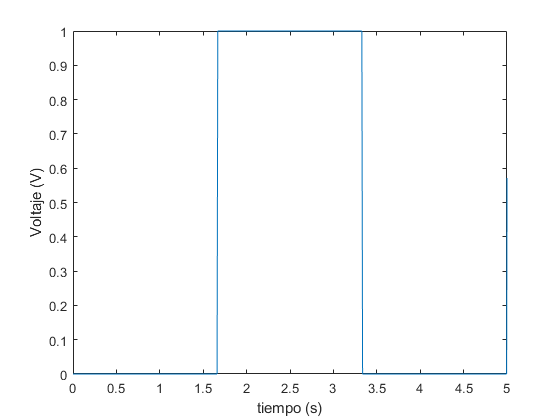

figure("Name","Ejercicio 5 b");
lin=plot(t,u);
xlim([0,1.5]);xlim([-0.5,2]);

xlabel('tiempo (s)');
ylabel('Voltaje (V)');

## Propiedades

### handles

Observe el uso de la función plot en el ejemplo anterior. La función plot devuelve lo que se conoce como un *handle *(o un array de *handles *en caso de representar más de una línea). Un *handle* es lo que se conoce como un puntero, que es un tipo especial de dato que 'señala' o 'apunta' a un objeto. En la práctica estos punteros nos permiten encontrar y acceder a los objetos que nos interesan de forma mucho más rápida.

Los *handles* son dinámicos, es decir, se crean cuando se crea un objeto, se mantienen asociados al objeto mientras éste existe, pero cuando los objetos se destruyen la asociación se rompe, permitiendo reutilizar el puntero para otro objeto.

El handle 0 es especial en MATLAB, hace referencia a la ventana principal de MATLAB, de la que provienen las demás ventanas (figuras). Los handles de números enteros más bajos se reservan también para las figuras. Así, si existe la figura, el handle 8 haría referencia a la figura 8.

### get, set

Las funciones *get* y *set* son funciones que permiten obtener (get) y modificar (set) las propiedades de los objetos, y entre éstos los distintos objetos que componen una figura. Utilizamos los *handles* para acceder a los distintos objetos.

Vamos a ver los atributos de la ventana principal.

get(0)

lin =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1200 double]
              YData: [1×1200 double]
              ZData: [1×0 double]

  Show all properties


Entre los atributos podemos encontrar *Children* y *Parent* que sirven para almacenar los hijos y padres de cada objeto. Como vimos al principio, los objetos de las figuras se organizan en una jerarquía. En el caso de la ventana principal no tiene un padre pero puede tener múltiples hijas (figuras). También vemos el atributo *Type* que indica el tipo de objeto. En el caso de la ventana principal es *root*.

El número de propiedades depende del tipo de objeto.

Abra en una ventana la figura creada anteriormente. En la parte superior debería ver el número de ventana. 

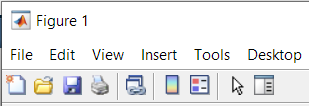

    Observe los atributos de la figura creada.

get(1)

ans = 'line'

    Verá que tiene una gran cantidad de propiedades. También podemos observar y modificar las propiedades de los demás objetos de la figura con el *Property Inspector*. Seleccionando la flecha   de la barra de herramientas y haciendo doble click sobre el objeto.

### gcf, gca, gco

Éstas dos funciones permiten obtener el handle de la figura actual (gcf, get current figure), del eje actual (gca, get current axis) y del objeto seleccionado (gco, get current object).

Veamos las propiedades de los ejes.

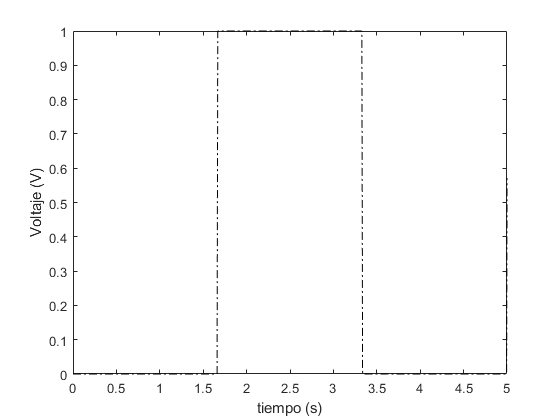

ax=gca
get(ax)

Podrá observar algunas propiedades que hemos estado tratando con anterioridad, XLabel, XLim o Title, además de otros muchos.

Para modificar estas propiedades podemos utilizar la función *set*, especificando la propiedad que queremos modificar y su nuevo valor.

set(ax,'XLim', [0,5]);  

### Notación de punto

En las útimas versiones de MATLAB se tiende a utilizar una notación más moderna, donde los atributos se pueden obtener y modificar sin recurrir a las funciones *get* y *set* mediante el uso del punto.

lin=ax.Children
lin.Type
lin.Color=[0 0 0];      
lin.LineStyle='-.';

## Ejercicios adicionales

**MATLAB Fundamentals. Plotting and Common Modifications**

[https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlbe](https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlbe)

**MATLAB for Data Processing and Visualization. **

**Graphics Formatting Functions & Customizing Graphics Objects**

[https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlvi](https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlvi)